clearvars;

$\theta$ is the elevation angle from $0$ to $\pi$

$\phi$ is the azimuth angle from $0$ to $2\pi$


$$\rho = \sqrt{(x^2+y^2+z^2)}$$



$$\theta = tan^{-1}\bigg(\frac{\sqrt{x^2+y^2}}{z}\bigg)$$



$$\phi = atan2\bigg(y,x\bigg) = tan^{-1}\bigg(\frac{y}{x}\bigg),\quad  x >0$$



$$x = \rho\sin\theta\cos\phi$$



$$y = \rho\sin\theta\sin\phi$$



$$z = \rho\cos\theta$$


#### Plane wave - Expansion in Spherical Harmonics

According to [https://en.wikipedia.org/wiki/Plane-wave_expansion](https://en.wikipedia.org/wiki/Plane-wave_expansion) as plane wave can be expressed as a linear combination of spherical harmonics:


$$e^{i\mathbf k \cdot \mathbf r} = 4 \pi \sum^\infty_{l=0}\sum_{m=-l}^l i^lj_l(kr)\overline Y_{lm}(\mathbf \hat k){Y}_{lm}(\mathbf \hat r),$$


where

$\overline Y_{lm} = (-1)^mY_{l,-m}$ is the complex conjugate matrix,

$i$ is the imaginary unit,

$\mathbf k$ is a wave vector of length $k$,

$\mathbf r$ is a position vector of length $r$,

$\mathbf \hat k = \frac{\mathbf k}{|\mathbf k|}$ and $\mathbf \hat r$ is the unit vector of $\mathbf k$ and $\mathbf r$ respectively.

in spherical coordinates  $\mathbf k\{\rho_k,\theta_k,\phi_k\}$ and  $\mathbf r\{\rho_r,\theta_r,\phi_r\}$.


$$e^{i \mathbf k \cdot \mathbf r} = 4 \pi \sum^\infty_{l=0}\sum_{m=-l}^l i^lj_l(\rho_k\rho_r)\overline Y_{lm}(\theta_k,\phi_k){Y}_{lm}(\theta_r,\phi_r),$$


where 


$$\mathbf k \cdot \mathbf r = \rho_k\rho_r[\sin\theta_k\sin\theta_r\cos(\phi_k-\phi_2)+\cos\theta_k\cos\theta_r]$$


$\rho_k = \frac{2\pi}{\lambda} = \frac{2\pi f}{c}$,

$\lambda$ is the wave length

## 1D Plane Wave Expansion - Legendre - Harmonics

### Initial Parameters

clearvars
n = 3; spacing = 0.1;
f = 200; c = 343; omega = 2*pi*f;
k = [omega/c;0;0];

rx = 0:spacing:2*n;
ry = 5; rz = 10;
sz = [length(ry) length(rx)];
r = [rx;ones(sz)*ry;ones(sz)*rz];

### Wave in Exponent Form

figure;
subplot(311);
wave = expWave(sz,r,k,1);

### Plane Wave Expansion - Legendre


$$e^{i\mathbf k \cdot \mathbf r} = \sum_{l=0}^\infty (2l+1)i^lj_l(kr)P_l(\hat \mathbf k \cdot\hat\mathbf r)$$


subplot(312);
P = legendreWave(r,k,1);

#### Compare

cmpWaves(P,wave,0);

ans = "Max real error:  7.11e-15"

ans = "Max imag error:  5.78e-15"

ans = "Mean error: 1.86e-15"

### Plane Wave Expansion - Harmonics


$$e^{i \mathbf k \cdot \mathbf r} = 4 \pi \sum^\infty_{l=0}\sum_{m=-l}^l i^lj_l(\rho_k\rho_r)Y_{lm}(\theta_k,\phi_k)\overline{Y}_{lm}(\theta_r,\phi_r),$$
 

or


$$e^{i \mathbf k \cdot \mathbf r} = 4 \pi \sum^\infty_{l=0}\sum_{m=-l}^l i^lj_l(\rho_k\rho_r)\overline Y_{lm}(\theta_k,\phi_k){Y}_{lm}(\theta_r,\phi_r),$$


### Harmonic Matrix - $Y_{lm}(\theta_k,\phi_k)$

[rho_k,the_k,phi_k] = my_cart2sph(k);
[rho_r,the_r,phi_r] = my_cart2sph(r);
L = ceil(exp(1)*rho_k*max(rho_r));
Yk = harmonicMatrix(L,the_k,phi_k);
cYk = conj(Yk);

### 1 - $\overline{Y}_{lm}(\theta_r,\phi_r)$

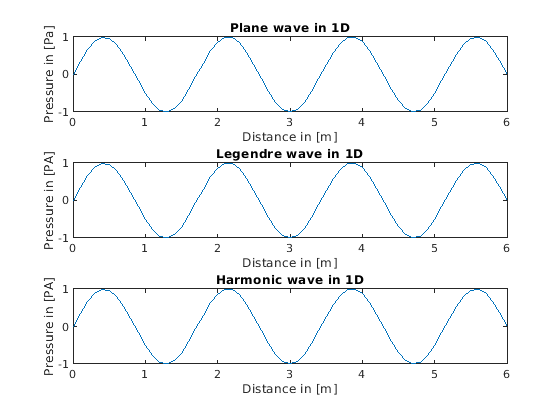

subplot(313);
P = harmonicWave(r,k,1);

cmpWaves(P,wave,0);

ans = "Max real error:  1.68e-09"

ans = "Max imag error:  9.19e-10"

ans = "Mean error: 1.06e-10"

## 2 Dimensions

### Initial Parameters

clearvars
n = 3; spacing = 0.1;
f = 200; c = 343; omega = 2*pi*f;
rho_k = omega/c;
phi_k = pi/4;
the_k = pi/2;
k = my_sph2cart(the_k,phi_k,rho_k);
[w,w1,w2] = my_cart2sph(k)

w = 3.6637

w1 = 1.5708

w2 = 0.7854

rx = 0:spacing:n;
ry = rx;
sz = [length(ry),length(rx)];
rz = ones(1,sz(1))*0;
r = [rx;ry;rz];

### 2D Plane Wave - Exponent Form

figure;
wave = expWave(sz,r,k,2);

### 2D Plane Wave Expansion - Legendre

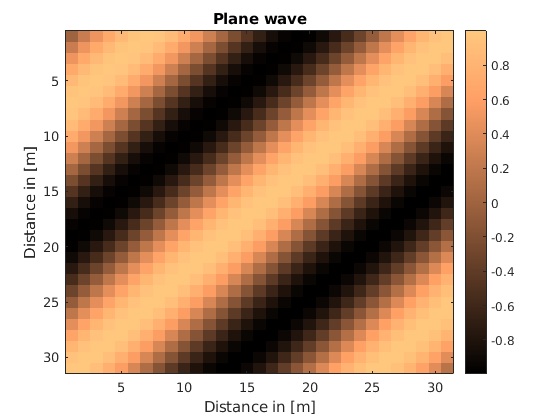

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 4).


Pl = zeros(sz);
h = waitbar(0,'init');
for idy = 1:sz(1)
    waitbar(idy/sz(1),h,"load");
    rInter = [r(1,:);ones(1,sz(2))*r(2,idy);r(3,:)];
    Pl(idy,:) = legendreWave(rInter,k,0);
end

close(h);
figure;
imagesc(imag(Pl)); colorbar;
title("Legendre Wave");

### Compare

cmpWaves(Pl,wave,1)

ans = "Max real error:  1.77e-07"

ans = "Max imag error:  6.73e-07"

ans = "Mean error: NaN"

sgtitle("Legendre Error");

### 2D Plane Wave Expansion - Harmonic

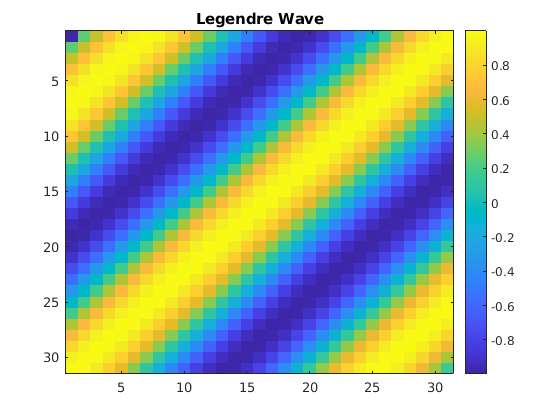

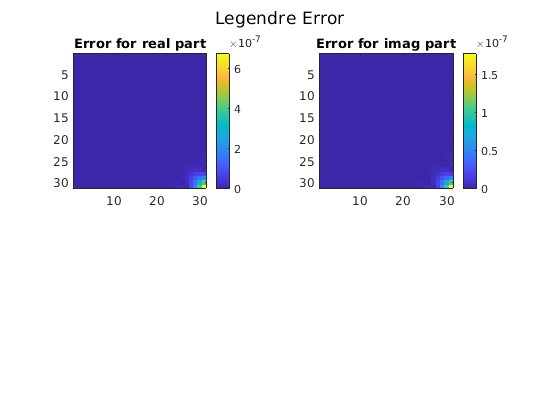

Ph = zeros(sz);
h = waitbar(0,'init');
for idy = 1:sz(1)
    waitbar(idy/sz(1),h,"load");
    rInter = [r(1,:);ones(1,sz(2))*r(2,idy);r(3,:)];
    Ph(idy,:) = harmonicWave(rInter,k,0);
end

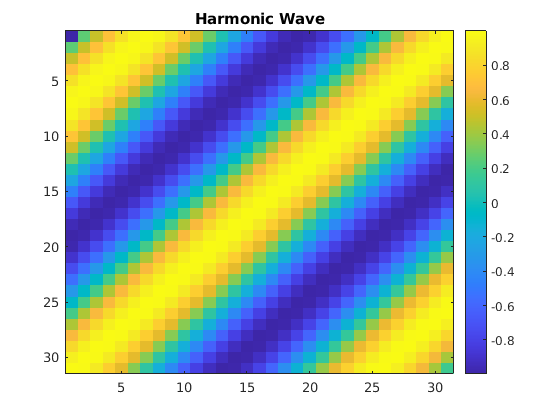

figure;
close(h);
imagesc(imag(Ph)); colorbar;
title("Harmonic Wave");

### Compare

cmpWaves(Ph,wave,1)

ans = "Max real error:  2.46e-03"

ans = "Max imag error:  6.56e-03"

ans = "Mean error: NaN"

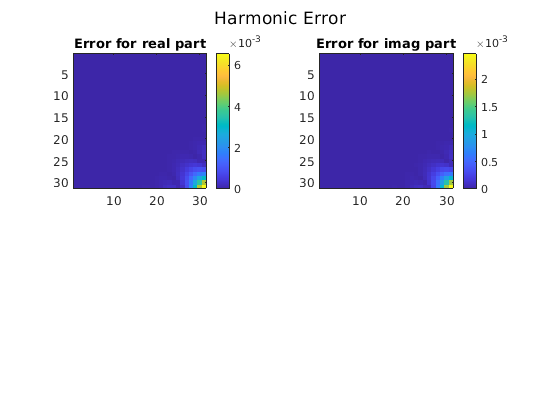

sgtitle("Harmonic Error");

### Plane Wave - Harmonic Coefficients

We have seen previously that a plane wave can be expressed as a linear combination of spherical harmonics as


$$e^{i \mathbf k \cdot \mathbf r} = 4 \pi \sum^\infty_{l=0}\sum_{m=-l}^l i^lj_l(\rho_k\rho_r)Y_{lm}(\theta_k,\phi_k)\overline{Y}_{lm}(\theta_r,\phi_r),$$


Due to symetrie the complex conjugation is interchangeable therefore


$$e^{i \mathbf k \cdot \mathbf r} = 4 \pi \sum^\infty_{l=0}\sum_{m=-l}^l i^lj_l(\rho_k\rho_r)\overline Y_{lm}(\theta_k,\phi_k){Y}_{lm}(\theta_r,\phi_r),$$


and


$$P(r,\theta,\phi,k) = \sum_{l=0}^\infty \sum_{m=-l}^l C_{lm}(k)j_l(kr)Y_{lm}(\theta,\phi)$$


therefore for a plane wave


$$4\pi i^lj_l(\rho_k\rho_r)\overline Y_{lm}(\theta_k,\phi_k){Y}_{lm}(\theta_r,\phi_r) = C_{lm}(k)j_l(kr)Y_{lm}(\theta_r,\phi_r)$$



$$\Leftrightarrow C_{lm}(k) = 4\pi i^l  \overline Y_{lm}(\theta_k,\phi_k)\frac{{Y}_{lm}(\theta_r,\phi_r) }{Y_{lm}(\theta_r,\phi_r)}$$



$$\Leftrightarrow C_{lm}(k) = 4\pi i^l  \overline Y_{lm}(\theta_k,\phi_k)$$


L = 60;
Yk = harmonicMatrix(L,the_k,phi_k);
Clm = 4.*pi.*1i.^((0:L).').*conj(Yk);
P = harmonics2pressure(Clm,k,r,sz);

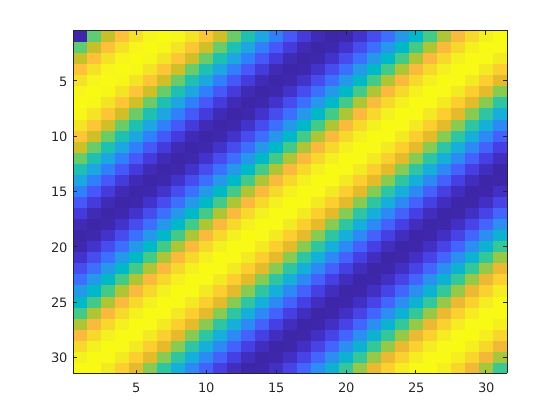

figure;
imagesc(imag(P));

title("Plane Wave - Harmonic Coefficients");